# Run Analysis on Test Brain Data

This notebook walks through a simplified version of the entire thesis. We use a known volume downloaded from [https://projects.iq.harvard.edu/sparcdmri/Challenge_Data](https://projects.iq.harvard.edu/sparcdmri/Challenge_Data) to run the analysis - in the process of which we demonstrate how the analysis works. 

clear
close

### Setting up the experiment

In this section, we create an experiment object, in which we setup some parameters of the phantom data. One of the contributions of this paper is a table of $\lambda$ values that is parameterized on the number of fibers, the b-values, SNR and the order of the spherical harmonics model that's used. The $\lambda$ is computed per b-value (shell) and all of these parameters are stored in the `csaodfExperiment` object. 

simpleExpt = csaodfExperiment;

gTable = gradientTable;
gTable.readFromBvecBval("data/bvec.txt", "data/bvalue.txt");

simpleExpt.fibers = 2;               % Estimated - this can't be known beforehand, but 2 is a good default (60% of voxels have crossings).
simpleExpt.SNR    = 30;              % This is also estimated from acquisition data.
simpleExpt.order  = 6;               % Higher values here -> sharper reconstruction; also noisier.
simpleExpt.bvals  = gTable.bValues;

% Compute optimal regularization factor - lambda.
simpleExpt.computeLambda();

% Experimentally computed weights for Laplace Beltrami regularization
simpleExpt.lambda

ans =     0.0046    0.0019    0.0002


### Read data from volume

Reading data from a volume is easy - use the readFromNii function to populate v.

phantomVolume = volume;
phantomVolume.readFromNii("data/Gradient_60.nii");

### Compute Spherical Harmonics transformation matrix

Using the gradient directions from the table above, we can then compute the spherical harmonics transformation matrix can be computed. The inputs necessary are the table and the order of the harmonics.

spHarmonicTform = sphericalHarmonicsMatrix(gTable.table, simpleExpt.order, 0);

### Process the volume!

processLive = false;

if processLive 
    ODFdata = simpleExpt.processVolume(phantomVolume, gTable, spHarmonicTform);
else
    % This is order 4
    d = load("data/ODFdataO6.mat");
    ODFdata = d.ODFdata;
end

### Visualize Data

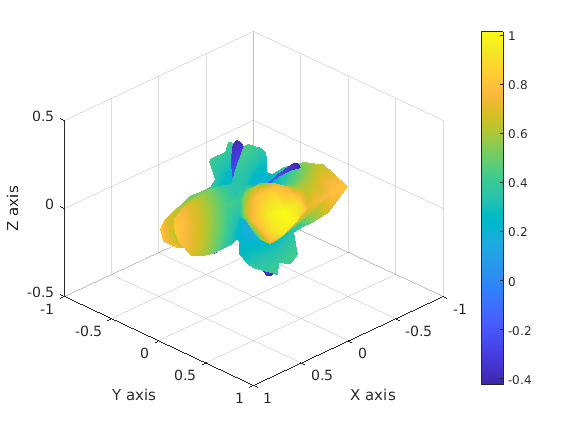

coeffData = ODFdata.dataAtVoxel(10,10,1,0,0);

% Choose a large number of uniform points for smoother visualization.
vizPoints = simpleExpt.genNSpherePoints(1000);

% Reconstruct data from coefficients - no lambda here.
shViz = sphericalHarmonicsMatrix(vizPoints, simpleExpt.order, 0);
reconstructedODF = shViz.coeffToSample(coeffData);

% Visualize reconstruction.
figure, 
simpleExpt.visualizeODF(reconstructedODF, vizPoints);